# **SCARA Manipulator: Inverse Kinematics Demonstration, Analytic and Numerical**

Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student 

Robotics 7752 | Ohio State University | 10/25/2022

with use of Modern Robotics by Kevin M. Lynch and Frank C. Park

**SCARA Background **

The SCARA-type robot is an architecture of form RRRP, widely used for table pick and place tasks. SCARA  stands for **Selective Compliance Articulated Robot Arm; **the arm is slightly compliant in the X-Y direction and rigid in the Z direction. 

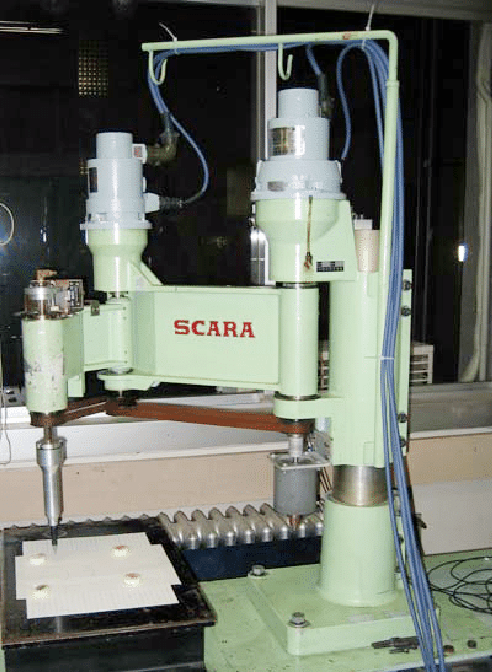

Photo from research gate 

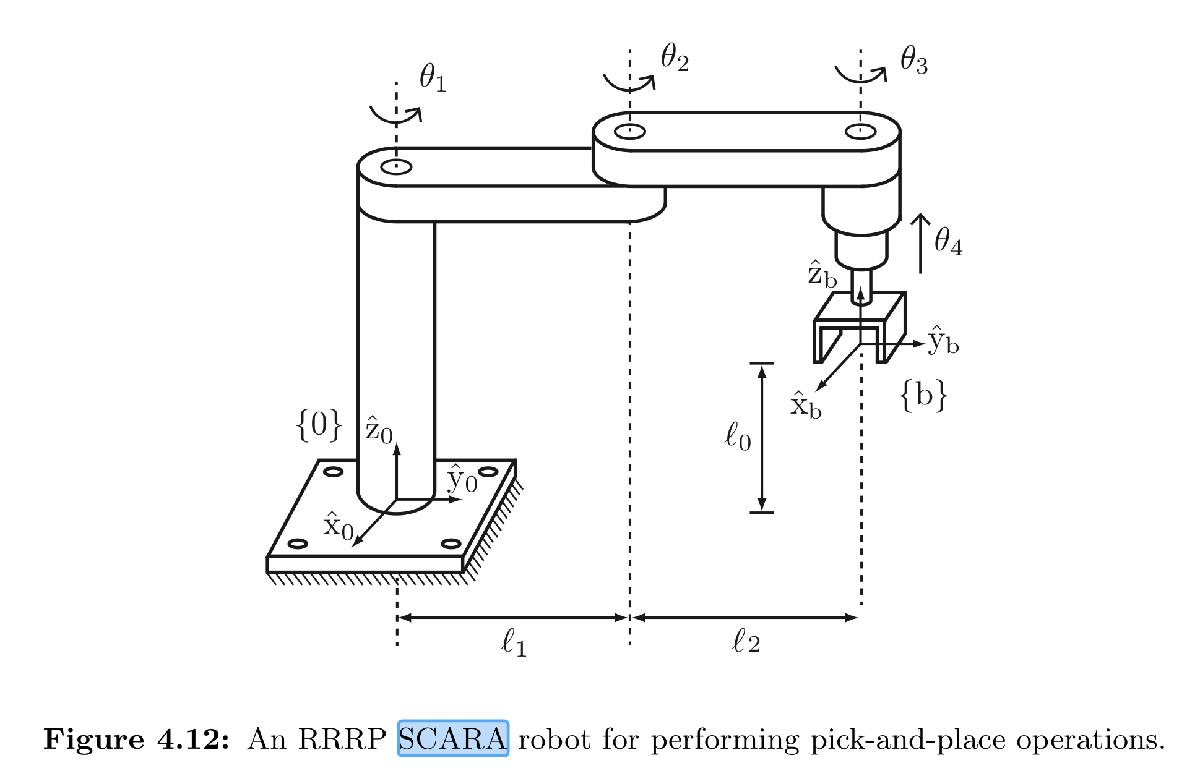

Photo from Textbook

Note that 

- links L1 and L2 with their respective joints make up a 2R planar system.

- theta 3 directly controls the orinetation of the end effector 

- theta 4 directly controls the Z Position (with L0 incorporated)

- The 2R solution differs by only the orientation  of the links with the X axis instread of y (above)

With these notes, it is relatively simple to convert the 2R planar analytic solution for inverse kinematics. 

# Beginning of SCARA Script

## General Setup

Variable clearing 

clc; clear; close all; 

Link Lengths

L0 = 1; L1=2; L2=2; L = [L0 L1 L2];

Home Config 

p = [0 L1+L2 L0]'; M = [[eye(3) ; 0 0 0] [p ; 1]];

Screw Axis

S1=[0 0 1 0 0 0]; S2=[0 0 1 L1 0 0]; 
S3=[0 0 1 L1+L2 0 0]; S4=[0 0 0 0 0 1];
Slist = [S1' S2' S3' S4']

Slist =      0     0     0     0
     0     0     0     0
     1     1     1     0
     0     2     4     0
     0     0     0     0
     0     0     0     1


## Analytic Inverse Kinematics

**The 2R planar solution **

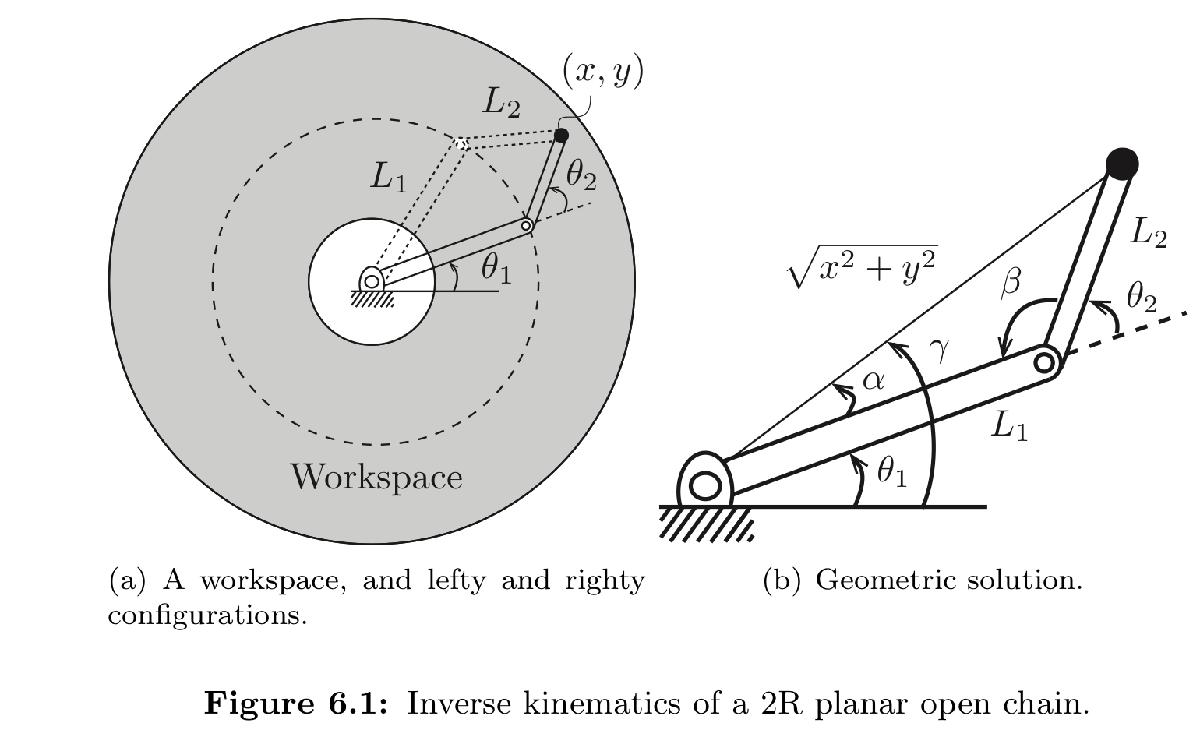

%Given T, find thetaList = [th1 th2 th3 th4]
p = [1 1 1]';
T = [[eye(3) ; 0 0 0] [p ; 1]]; %test T=M to check correctness
T=M;
%2R solution - to get th1 th2
    %Reformat - accounting for 2R solutions difference in frames
    p = T(1:3,4); 
    x = p(2);
    y = p(1);
    %Solution
    [thetasRighty thetasLefty] = IK_2R(x,y,L); %th1 and th2 
%th4 is soley dependant on z and L0
    z = T(3,4);
    th4 = z - L0;
%th3 is soley dependant on the orientation of the new end effector X axis
    y = T(2,1); x = T(1,1);
    th3 = atan2(y,x);

**The Analytic Inverse Kinematics Solutions **

thetaRighty = [thetasRighty' th3 th4]*180/pi

thetaRighty =      0     0     0     0


thetaLefty = [thetasLefty' th3 th4]*180/pi

thetaLefty =      0     0     0     0


## Numeric Inverse Kinematics Solution

    Newton-Raphson method

    notes:

    J^-1 : it is better to use X=A\b which solves x without computing A^-1 OR use 

    Moore-Penrose psuedoinverse : by use of matlab command y = pinv(J) * z

%Input
T = M; 
eomg = 0.01; ev = 0.01;
thetalist0 = [1 0 1 1/2];
%Output, function using partial textbook library 
[thetalist, success] = IKinSpace(Slist, M, T, thetalist0, eomg, ev)

thetalist =     0.0584   -0.9416    0.0584   -0.4416
   -0.1167   -1.1167   -0.1167   -0.6167
    0.0584   -0.9416    0.0584   -0.4416
         0   -1.0000         0   -0.5000


success = logical
   1


thetalist*pi/180 %In degrees, pretty good, fits requirements

ans =     0.0010   -0.0164    0.0010   -0.0077
   -0.0020   -0.0195   -0.0020   -0.0108
    0.0010   -0.0164    0.0010   -0.0077
         0   -0.0175         0   -0.0087


# Analytic 2R Functions

function [thetasRighty thetasLefty] = IK_2R(x,y,L)
    L1 = L(2); L2 = L(3);
    if (norm(x,y) < L1-L2 || norm(x,y) > L1+L2)
        disp('no solution exists')
        return
    end 
    temp = (L1^2+L2^2 - x^2 - y^2)/(2*L1*L2);
    beta = acos(temp); 
    temp = (x^2 + y^2 + L1^2 - L2^2)/(2*L1*(x^2+y^2)^.5);
    alpha = acos(temp);
    gamma = atan2(y,x);
    %The Righty Solution
    th1R = gamma - alpha;
    th2R = pi - beta;
    thetasRighty = [th1R th2R]';
    %The Lefty Solution 
    th1L = gamma + alpha;
    th2L = beta - pi;
    thetasLefty = [th1L th2L]';
end
function rot = rotz(ang) %in radians
    rot = [cos(ang) -sin(ang) 0 ; sin(ang) cos(ang) 0 ; 0 0 1];
end 

# Jacobian Functions 

Jacobian Calculation from Modified Modern Robotics Library and book theory

Functions

The Jacobian Calculation 

%Input the screw axis list, S
%t = [0 0 0 0]; %theta list
%Output the Jacobian, J
%Js=JacobianSpace(Slist,t)
function Js = JacobianSpace(Slist,thetalist) %REWRITTEN PARTIALLY
Js = Slist; %sets J1=S1
T = eye(4);
for i = 2: length(thetalist) %starts at making J2 
    %[Si]
    Smatrix = VecTose3(Slist(:, i - 1));
    %e^[Si]*theta
    mexp = MatrixExp6(Smatrix*thetalist(i - 1));
    %??
    T = T * mexp;
	Js(:, i) = Adjoint(T) * Slist(:, i);
end
end
    function se3mat = VecTose3(V)
    % in -> 6*1 vector
    % out -> 4x4 se(3) matrix.
    se3mat = [VecToso3(V(1: 3)), V(4: 6); 0, 0, 0, 0];
    end

    function T = MatrixExp6(se3mat)
    omgtheta = so3ToVec(se3mat(1: 3, 1: 3));
    if NearZero(norm(omgtheta))
        T = [eye(3), se3mat(1: 3, 4); 0, 0, 0, 1];
    else
        [omghat, theta] = AxisAng3(omgtheta);
        omgmat = se3mat(1: 3, 1: 3) / theta; 
        T = [MatrixExp3(se3mat(1: 3, 1: 3)), ...
            (eye(3) * theta + (1 - cos(theta)) * omgmat ...
            + (theta - sin(theta)) * omgmat * omgmat) ...
                * se3mat(1: 3, 4) / theta;
            0, 0, 0, 1];
    end
    end
        function omg = so3ToVec(so3mat)
            omg = [so3mat(3, 2); so3mat(1, 3); so3mat(2, 1)];
        end
        function so3mat = VecToso3(omg)
            so3mat = [0, -omg(3), omg(2); omg(3), 0, -omg(1); -omg(2), omg(1), 0];
        end
        function [omghat, theta] = AxisAng3(expc3)
            theta = norm(expc3);
            omghat = expc3 / theta;
        end
        function  R = MatrixExp3(so3mat)
            omgtheta = so3ToVec(so3mat);
            if NearZero(norm(omgtheta))
                R = eye(3);
            else
                [omghat, theta] = AxisAng3(omgtheta);
                omgmat = so3mat / theta;
                R = eye(3) + sin(theta) * omgmat ...
                    + (1 - cos(theta)) * omgmat * omgmat;
            end
            end
        function judge = NearZero(near)
            judge = norm(near) < 1e-6;
        end
function AdT = Adjoint(T)
    [R, p] = TransToRp(T);
    AdT = [R, zeros(3); VecToso3(p) * R, R];
end
function [R, p] = TransToRp(T)
    R = T(1: 3, 1: 3);
    p = T(1: 3, 4);
end

Forward Kinematics in Space modified from Modern Robotics Lynch and textbook

function T = FKinSpace(M, Slist, thetalist)
T = M;
for i = size(thetalist): -1: 1
    T = MatrixExp6(VecTose3(Slist(:, i) * thetalist(i))) * T;
end
end

Inverse Kinematics

function [thetalist, success] ...
         = IKinSpace(Slist, M, T, thetalist0, eomg, ev)
% *** CHAPTER 6: INVERSE KINEMATICS ***
% Takes Slist: The joint screw axes in the space frame when the manipulator
%              is at the home position, in the format of a matrix with the
%              screw axes as the columns,
%       M: The home configuration of the end-effector,
%       T: The desired end-effector configuration Tsd,
%       thetalist0: An initial guess of joint angles that are close to 
%                   satisfying Tsd,
%       eomg: A small positive tolerance on the end-effector orientation 
%             error. The returned joint angles must give an end-effector 
%             orientation error less than eomg,
%       ev: A small positive tolerance on the end-effector linear position 
%           error. The returned joint angles must give an end-effector 
%           position error less than ev.
% Returns thetalist: Joint angles that achieve T within the specified 
%                    tolerances,
%         success: A logical value where TRUE means that the function found
%                  a solution and FALSE means that it ran through the set 
%                  number of maximum iterations without finding a solution
%                  within the tolerances eomg and ev.
% Uses an iterative Newton-Raphson root-finding method.
% The maximum number of iterations before the algorithm is terminated has 
% been hardcoded in as a variable called maxiterations. It is set to 20 at 
% the start of the function, but can be changed if needed.  

thetalist = thetalist0;
i = 0;
maxiterations = 20;
%Forward Kinematics
Tsb = FKinSpace(M, Slist, thetalist);
%Inverse of T
[R, p] = TransToRp(Tsb);
invT = [transpose(R), -transpose(R) * p; 0, 0, 0, 1];
%6 vector velocity twist from 4x4 representation
se3mat = MatrixLog6(invT * T); %the initial twist created from the difference in T and Tinv
V = [se3mat(3, 2); se3mat(1, 3); se3mat(2, 1); se3mat(1: 3, 4)]; 
%Twist adjoint 
Vs = Adjoint(Tsb) * V;
err = norm(Vs(1: 3)) > eomg || norm(Vs(4: 6)) > ev;
%Numerical Iteration loop
while err && i < maxiterations
    thetalist = thetalist + pinv(JacobianSpace(Slist, thetalist)) * Vs;
    i = i + 1;
    Tsb = FKinSpace(M, Slist, thetalist);
    %Inverse of T
        [R, p] = TransToRp(Tsb);
        Tinv = [transpose(R), -transpose(R) * p; 0, 0, 0, 1];
    %Twist
        %6 vector velocity twist from 4x4 representation
            se3mat = MatrixLog6(Tinv * T); %the initial twist created from the difference in T and Tinv
            V = [se3mat(3, 2); se3mat(1, 3); se3mat(2, 1); se3mat(1: 3, 4)]; 
        Vs = Adjoint(Tsb) * V;
    %Error
    err = norm(Vs(1: 3)) > eomg || norm(Vs(4: 6)) > ev;
end
success = ~ err;
end
function expmat = MatrixLog6(T)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a transformation matrix T in SE(3).
% Returns the corresponding se(3) representation of exponential 
% coordinates.

[R, p] = TransToRp(T);
omgmat = MatrixLog3(R);
if isequal(omgmat, zeros(3))
    expmat = [zeros(3), T(1: 3, 4); 0, 0, 0, 0];
else
    theta = acos((trace(R) - 1) / 2);
    expmat = [omgmat, (eye(3) - omgmat / 2 ...
                      + (1 / theta - cot(theta / 2) / 2) ...
                        * omgmat * omgmat / theta) * p;
              0, 0, 0, 0];    
end
end
function so3mat = MatrixLog3(R)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes R (rotation matrix).
% Returns the corresponding so(3) representation of exponential 
% coordinates.

acosinput = (trace(R) - 1) / 2;
if acosinput >= 1
    so3mat = zeros(3);
elseif acosinput <= -1
    if ~NearZero(1 + R(3, 3))
        omg = (1 / sqrt(2 * (1 + R(3, 3)))) ...
              * [R(1, 3); R(2, 3); 1 + R(3, 3)];
    elseif ~NearZero(1 + R(2, 2))
        omg = (1 / sqrt(2 * (1 + R(2, 2)))) ...
              * [R(1, 2); 1 + R(2, 2); R(3, 2)];
    else
        omg = (1 / sqrt(2 * (1 + R(1, 1)))) ...
              * [1 + R(1, 1); R(2, 1); R(3, 1)];
    end
    so3mat = VecToso3(pi * omg);
else
	theta = acos(acosinput);
    so3mat = theta * (1 / (2 * sin(theta))) * (R - R');
end
end
function invT = TransInv(T)
[R, p] = TransToRp(T);
invT = [transpose(R), -transpose(R) * p; 0, 0, 0, 1];
end